# Import in batch & Preprocess

**Step One**: Import .xlsx files into a struture array en masse

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\data");
addpath(fpath,dpath)

sensor_position = 97.5:7.5:270;

% path to the folder containing all data
folderPath = 'C:\Users\regen\Documents\MATLAB\data'; % one-time use

% extract the file names for all .xlsx files in the folder
fileList = dir(fullfile(folderPath, '*.xlsx')); % one-time use

% initialize a structure array with two fields
tableStruct = struct('tableName', {}, 'tableContents', {});

% automated file reading
for i = 1:numel(fileList)
    % create a path to the ith file with fullfile() function
    filePath_i = fullfile(folderPath, fileList(i).name);
    
    % import the ith file (as table)
    data_table = readtable(filePath_i,"TextType","string"); 
    
    % extract file name (without the extention .xlsx)
    [~, tableName, ~] = fileparts(fileList(i).name);

    % add the name and contents of the ith file to the structure array
    tableStruct(i).tableName = tableName;
    tableStruct(i).tableContents = data_table;
    % add description (table.Properties.Description)
    tableStruct(i).tableContents.Properties.Description = tableName;

end 


% check results
disp("tableStruct中有"+numel(tableStruct)+"张表格，它们的名字分别是：")

tableStruct中有8张表格，它们的名字分别是：


for i = 1:numel(tableStruct)
    disp("TableName: " + tableStruct(i).tableName)
    disp("Description: " + tableStruct(i).tableContents.Properties.Description)
end

TableName: data_10MPa_0.98h_Oil_60_deg_100_Cycles


Description: data_10MPa_0.98h_Oil_60_deg_100_Cycles


TableName: data_10MPa_1.00h_Oil_20_deg_Stepped


Description: data_10MPa_1.00h_Oil_20_deg_Stepped


TableName: data_10MPa_1.00h_Oil_60_deg_Stepped


Description: data_10MPa_1.00h_Oil_60_deg_Stepped


TableName: data_10MPa_1.11h_Oil_20_deg_40_Cycles


Description: data_10MPa_1.11h_Oil_20_deg_40_Cycles


TableName: data_10MPa_1.12h_Oil_60_deg_40_Cycles_99s


Description: data_10MPa_1.12h_Oil_60_deg_40_Cycles_99s


TableName: data_10MPa_118s_Oil_20_deg_Spontanversagen


Description: data_10MPa_118s_Oil_20_deg_Spontanversagen


TableName: data_15MPa_1.00h_Oil_60_deg_Stepped


Description: data_15MPa_1.00h_Oil_60_deg_Stepped


TableName: data_15MPa_6xh_Oil_60_deg_Plateau_discontinued


Description: data_15MPa_6xh_Oil_60_deg_Plateau_discontinued



clear data_table tableName folderPath fileList

**Step Two**: Create three smaller structure arrays from tableStruct:

- tableStruct_Stepped, 

- tableStruct_Cycles, 

- tableStruct_Plateau.

% initialize the three smaller structure arrays (numel = 0)
tableStruct_Stepped = struct('tableName', {}, 'tableContents', {});
tableStruct_Cycles = struct('tableName', {}, 'tableContents', {});
tableStruct_Plateau = struct('tableName', {}, 'tableContents', {});

% automatic allocation based on tableName
for i = 1:numel(tableStruct)
    if contains(tableStruct(i).tableName,"Stepped")
        idx = numel(tableStruct_Stepped)+1;
        tableStruct_Stepped(idx).tableName = tableStruct(i).tableName;
        tableStruct_Stepped(idx).tableContents = tableStruct(i).tableContents;
    elseif contains(tableStruct(i).tableName,"Cycles")
        idx = numel(tableStruct_Cycles)+1;
        tableStruct_Cycles(idx).tableName = tableStruct(i).tableName;
        tableStruct_Cycles(idx).tableContents = tableStruct(i).tableContents;
    elseif contains(tableStruct(i).tableName,"Plateau")
        idx = numel(tableStruct_Plateau)+1;
        tableStruct_Plateau(idx).tableName = tableStruct(i).tableName;
        tableStruct_Plateau(idx).tableContents = tableStruct(i).tableContents;
    end
end

clear tableStruct idx i 


% check results
disp("tableStruct_Stepped中有"+numel(tableStruct_Stepped)+"张表格，它们的名字分别是：")

tableStruct_Stepped中有3张表格，它们的名字分别是：


for i = 1:numel(tableStruct_Stepped)
    disp(tableStruct_Stepped(i).tableName)
    num_rows = height(tableStruct_Stepped(i).tableContents)
end

data_10MPa_1.00h_Oil_20_deg_Stepped


num_rows = 508

data_10MPa_1.00h_Oil_60_deg_Stepped


num_rows = 503

data_15MPa_1.00h_Oil_60_deg_Stepped


num_rows = 506


disp("tableStruct_Cycles中有"+numel(tableStruct_Cycles)+"张表格，它们的名字分别是：")

tableStruct_Cycles中有3张表格，它们的名字分别是：


for i = 1:numel(tableStruct_Cycles)
    disp(tableStruct_Cycles(i).tableName)
    num_rows = height(tableStruct_Cycles(i).tableContents)
end

data_10MPa_0.98h_Oil_60_deg_100_Cycles


num_rows = 496

data_10MPa_1.11h_Oil_20_deg_40_Cycles


num_rows = 566

data_10MPa_1.12h_Oil_60_deg_40_Cycles_99s


num_rows = 565


disp("tableStruct_Plateau中有"+numel(tableStruct_Plateau)+"张表格，它们的名字分别是：")

tableStruct_Plateau中有1张表格，它们的名字分别是：


for i = 1:numel(tableStruct_Plateau)
    disp(tableStruct_Plateau(i).tableName)
    num_rows = height(tableStruct_Plateau(i).tableContents)
end

data_15MPa_6xh_Oil_60_deg_Plateau_discontinued


num_rows = 798

**Step Three**: Preprocessing

Delete unwanted contents and standardize variable names.

% Stepped Data
for i = 1:numel(tableStruct_Stepped)  
    disp(tableStruct_Stepped(i).tableName);

    %% preprocessing
    data_table = preprocess(tableStruct_Stepped(i).tableContents); 
    
    %% update tableStruct_Stepped
    tableStruct_Stepped(i).tableContents = data_table;   
end

data_10MPa_1.00h_Oil_20_deg_Stepped
data_10MPa_1.00h_Oil_60_deg_Stepped
data_15MPa_1.00h_Oil_60_deg_Stepped



% Cycles Data
for i = 1:numel(tableStruct_Cycles)  
    disp(tableStruct_Cycles(i).tableName);

    %% preprocessing
    data_table = preprocess(tableStruct_Cycles(i).tableContents); 
    
    %% update tableStruct_Cycles
    tableStruct_Cycles(i).tableContents = data_table;   
end

data_10MPa_0.98h_Oil_60_deg_100_Cycles
data_10MPa_1.11h_Oil_20_deg_40_Cycles
data_10MPa_1.12h_Oil_60_deg_40_Cycles_99s



% Plateau Data
for i = 1:numel(tableStruct_Plateau)  
    disp(tableStruct_Plateau(i).tableName);

    %% preprocessing
    data_table = preprocess(tableStruct_Plateau(i).tableContents); 
    
    %% update tableStruct_Plateau
    tableStruct_Plateau(i).tableContents = data_table;   
end

data_15MPa_6xh_Oil_60_deg_Plateau_discontinued


## Stepped Data

Visualization

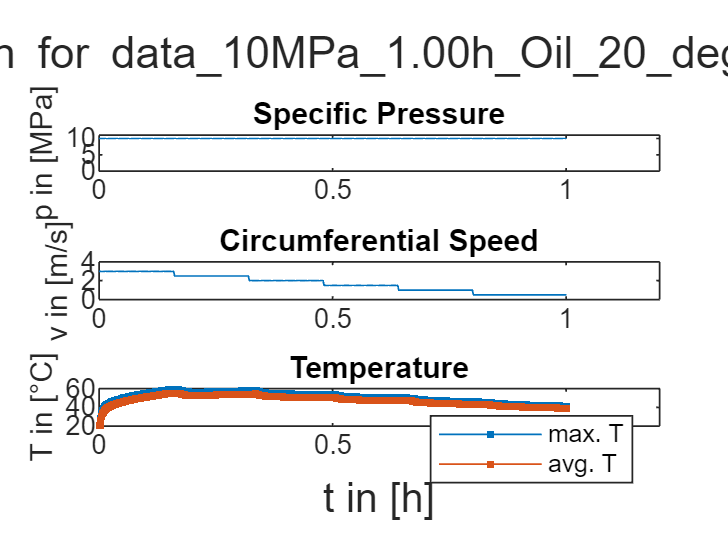

The documented max. T reached 58.875 ℃.


Animation for data_10MPa_1.00h_Oil_20_deg_Stepped: 


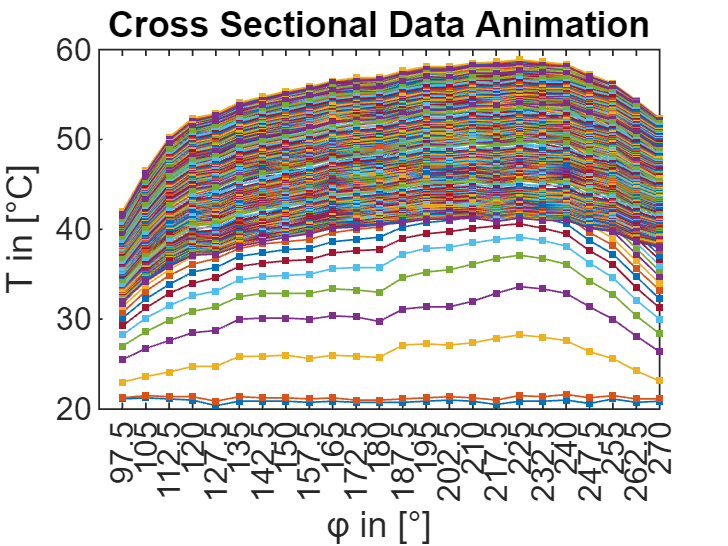

T_max position of data_10MPa_1.00h_Oil_20_deg_Stepped: 


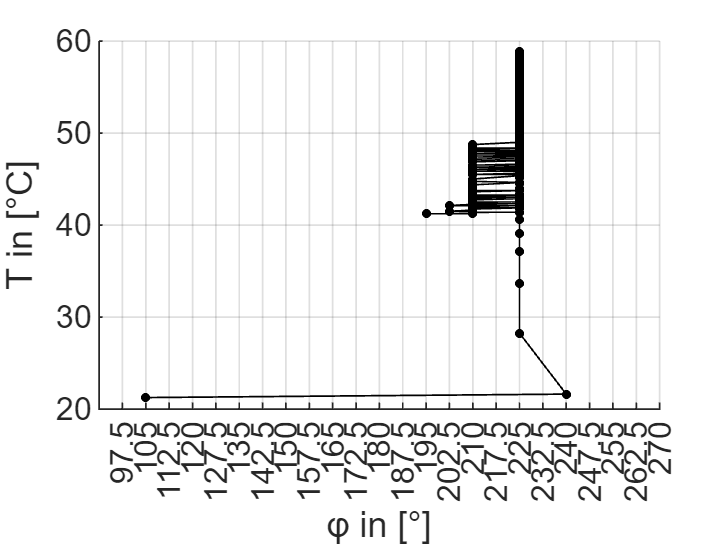

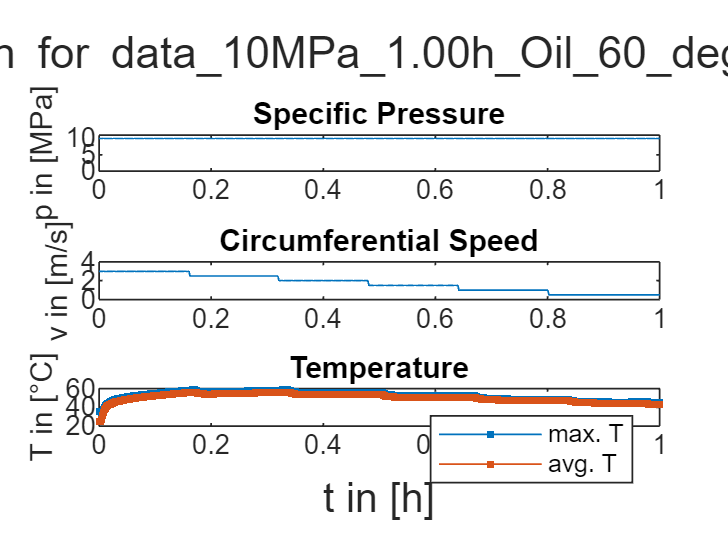

The documented max. T reached 58.625 ℃.


Animation for data_10MPa_1.00h_Oil_60_deg_Stepped: 


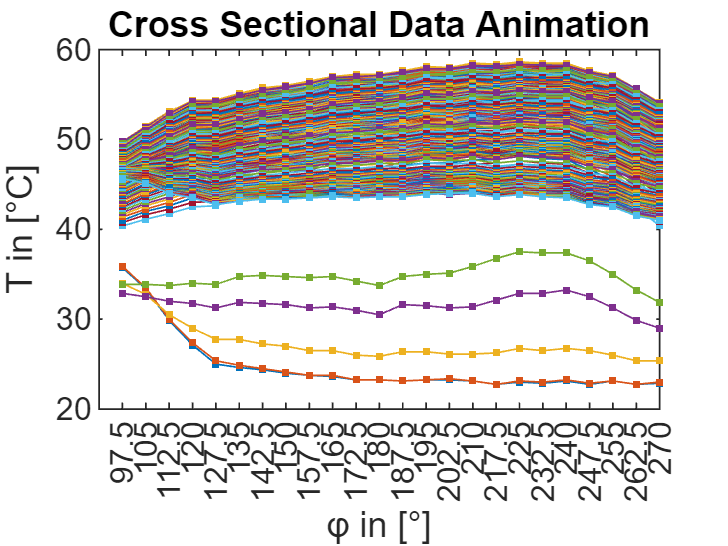

T_max position of data_10MPa_1.00h_Oil_60_deg_Stepped: 


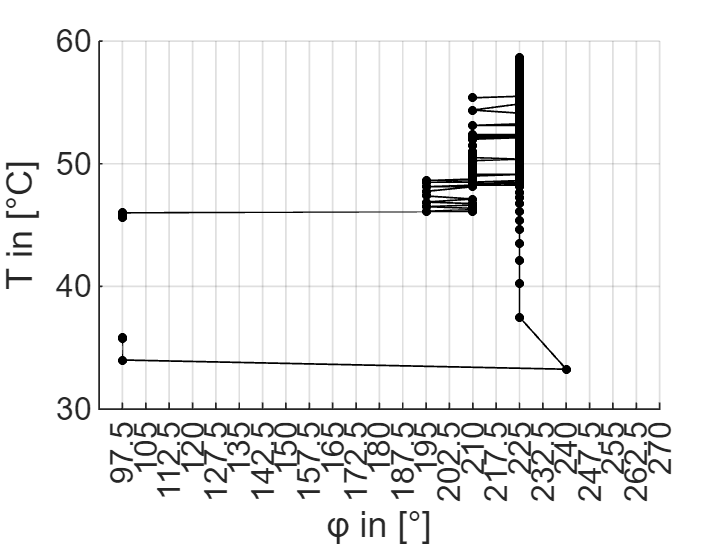

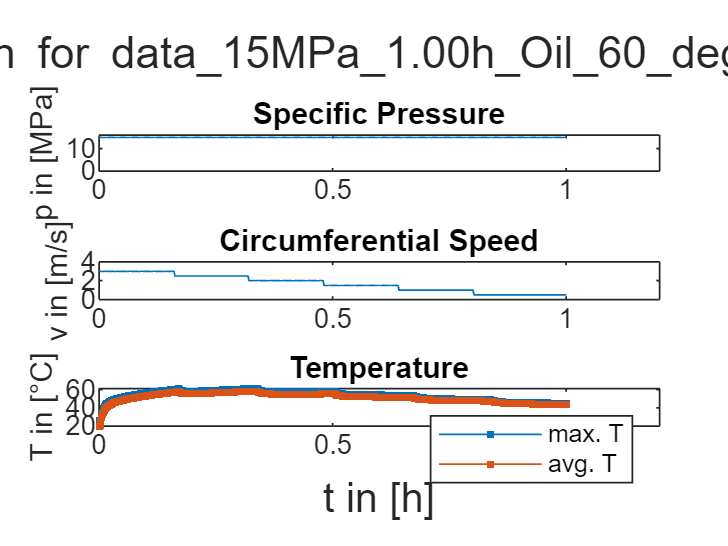

The documented max. T reached 61.125 ℃.


Animation for data_15MPa_1.00h_Oil_60_deg_Stepped: 


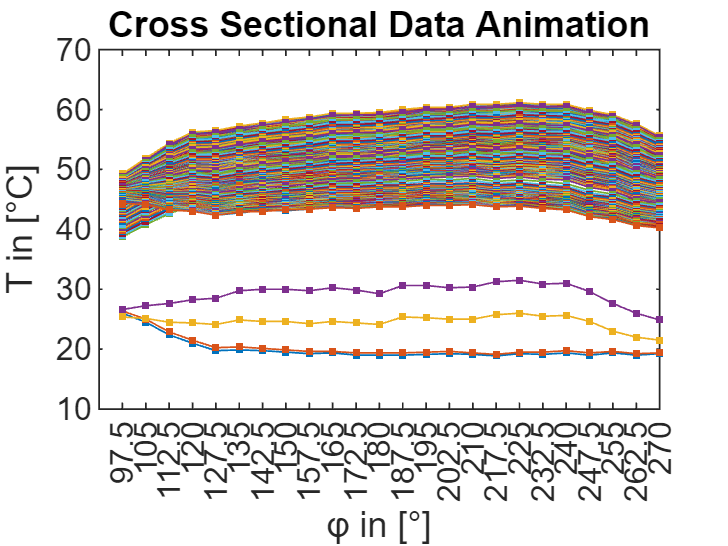

T_max position of data_15MPa_1.00h_Oil_60_deg_Stepped: 


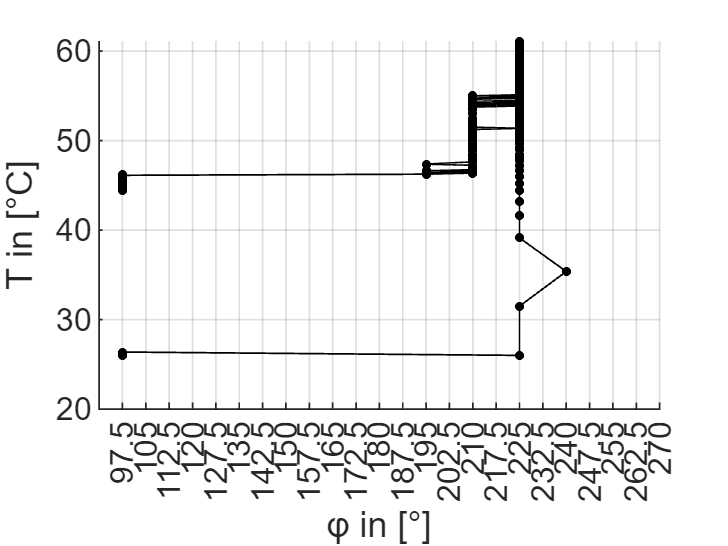

T_max position of data_10MPa_1.00h_Oil_60_deg_Stepped: 


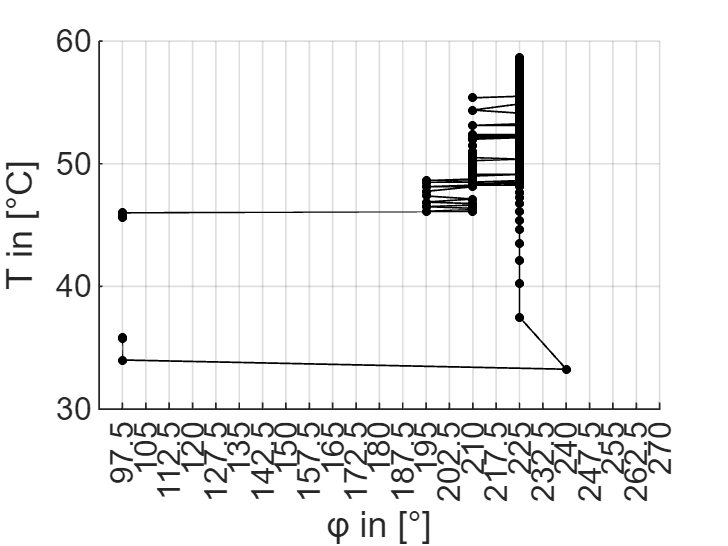

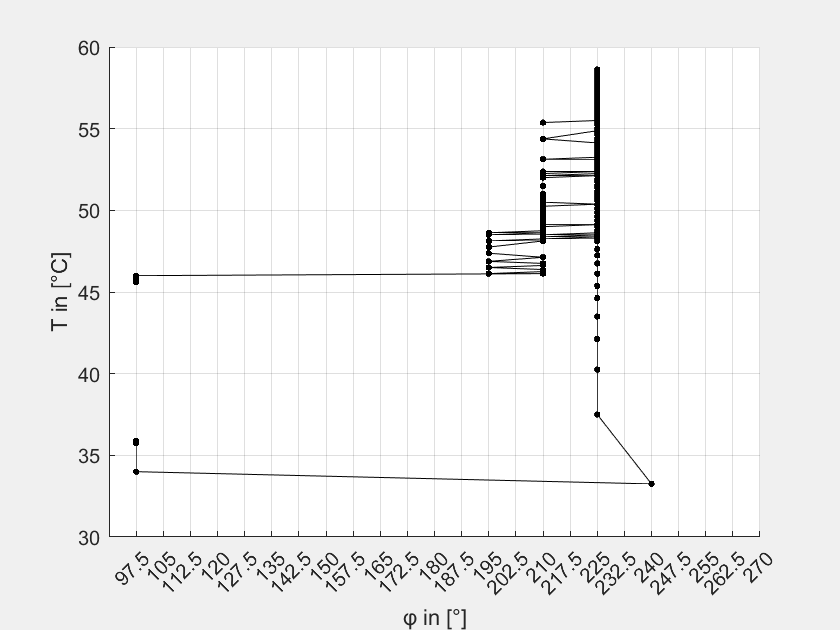

for i = 1:numel(tableStruct_Stepped)
    t = tableStruct_Stepped(i).tableContents;
    %% visualize test plan
    testplan_visualization(t); 

    %% time cross-sectional animation
    timeCrossSection_animation(sensor_position,t,1);

    %% animation of T_max position 
    maxT_position_animation(sensor_position,t);
end

## Cycles Data

Visualization

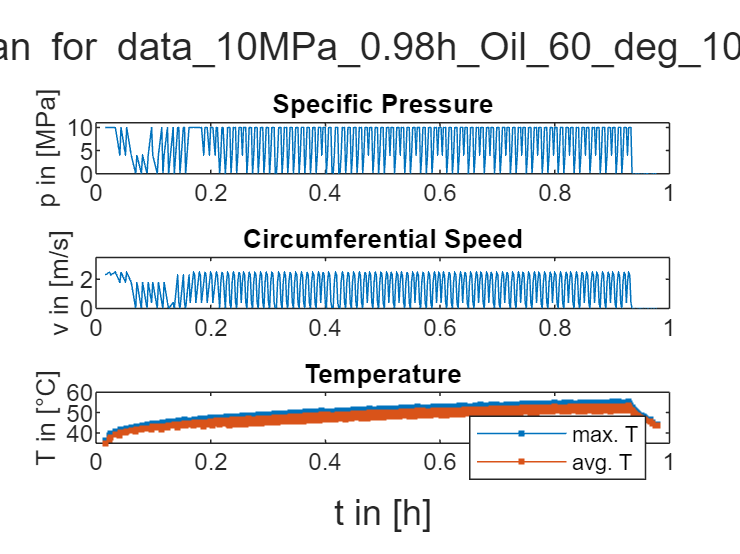

The documented max. T reached 55.375 ℃.


Animation for data_10MPa_0.98h_Oil_60_deg_100_Cycles: 


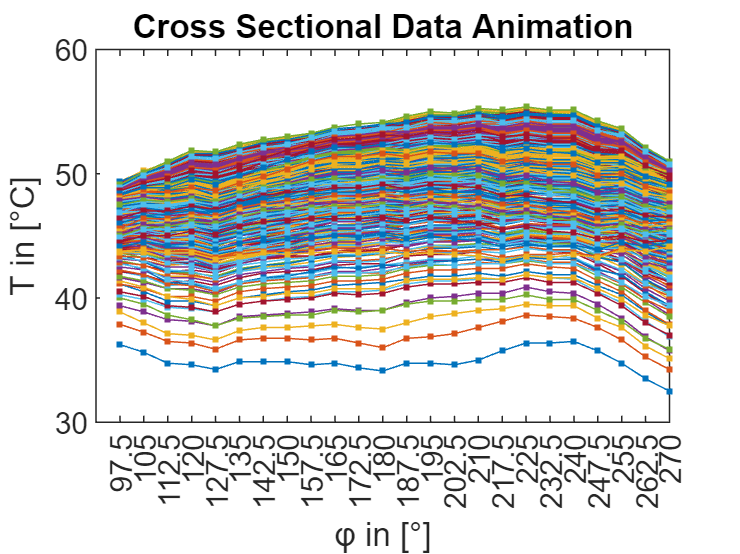

T_max position of data_10MPa_0.98h_Oil_60_deg_100_Cycles: 


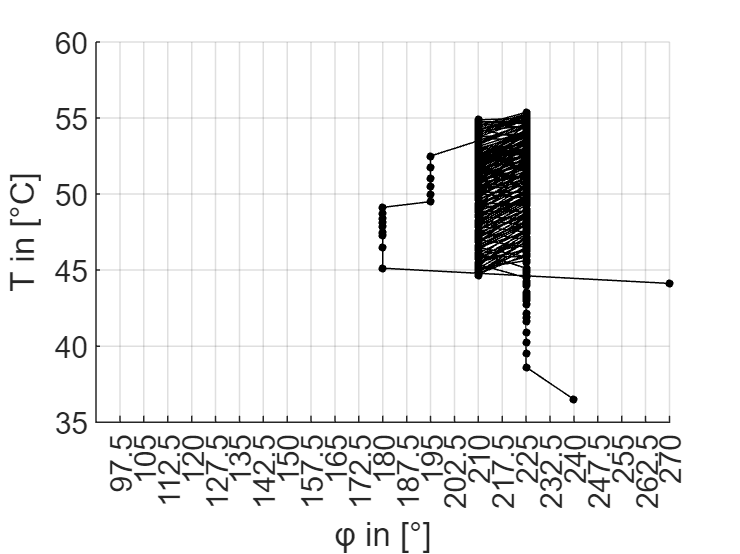

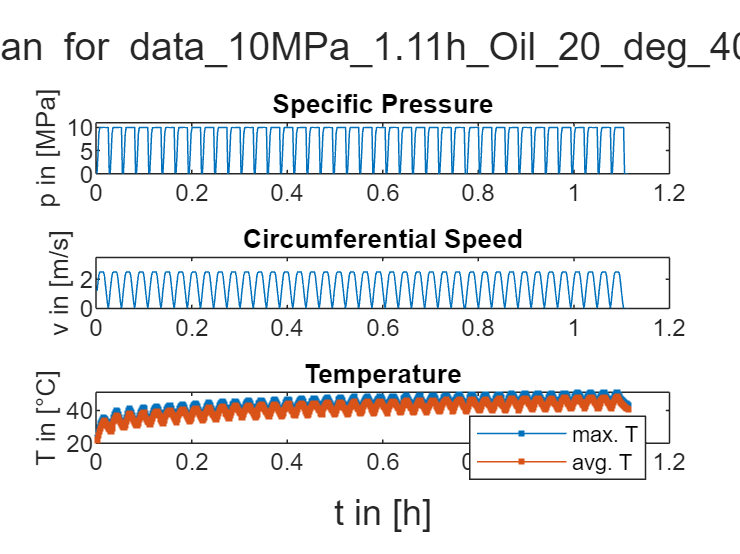

The documented max. T reached 51.125 ℃.


Animation for data_10MPa_1.11h_Oil_20_deg_40_Cycles: 


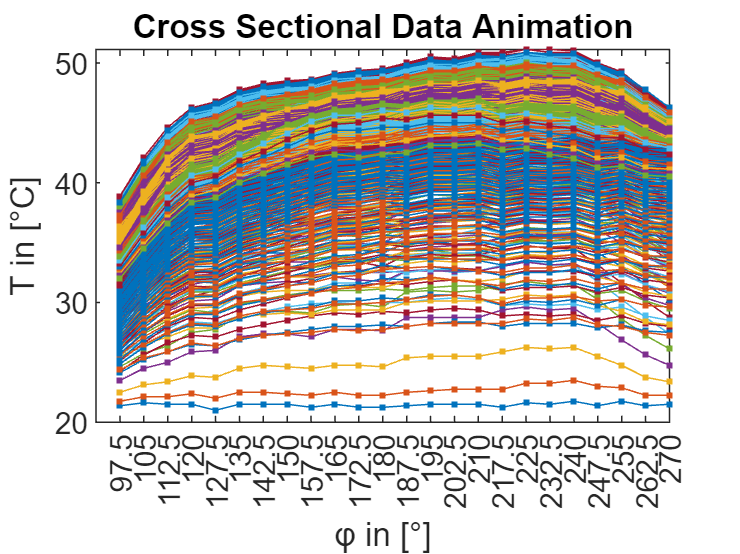

T_max position of data_10MPa_1.11h_Oil_20_deg_40_Cycles: 


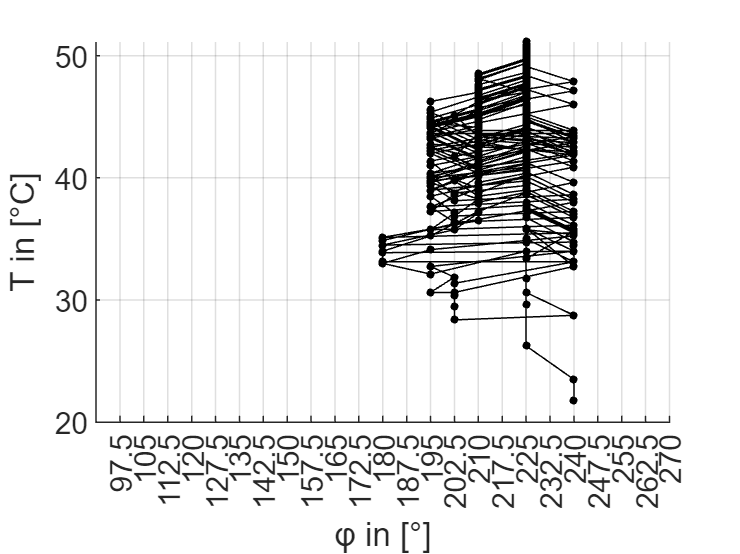

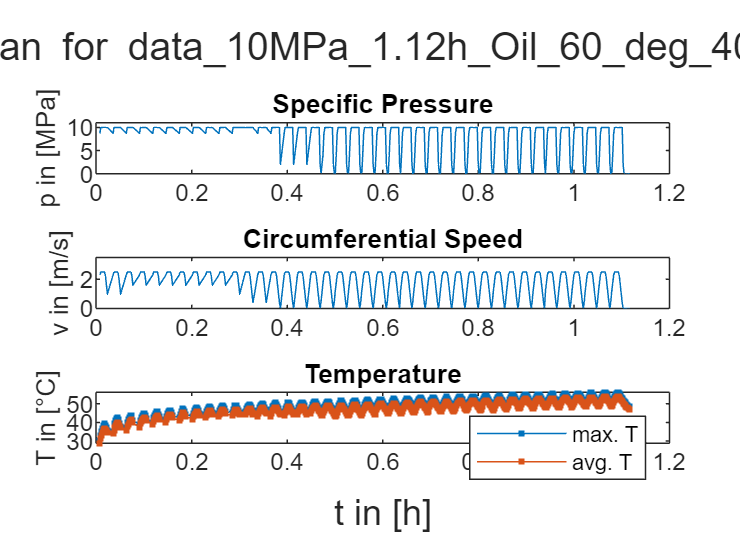

The documented max. T reached 56.25 ℃.


Animation for data_10MPa_1.12h_Oil_60_deg_40_Cycles: 


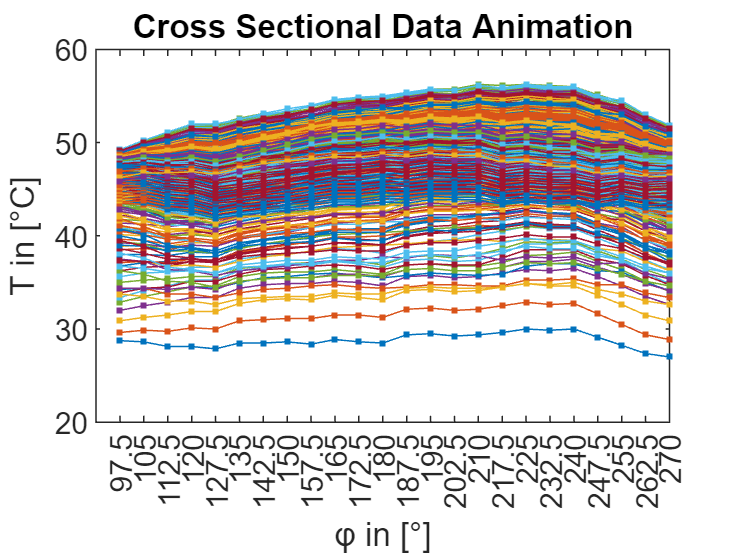

T_max position of data_10MPa_1.12h_Oil_60_deg_40_Cycles: 


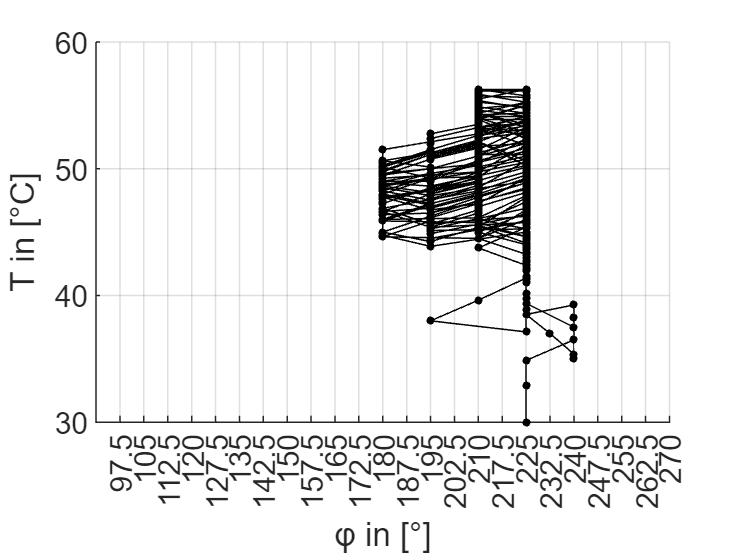

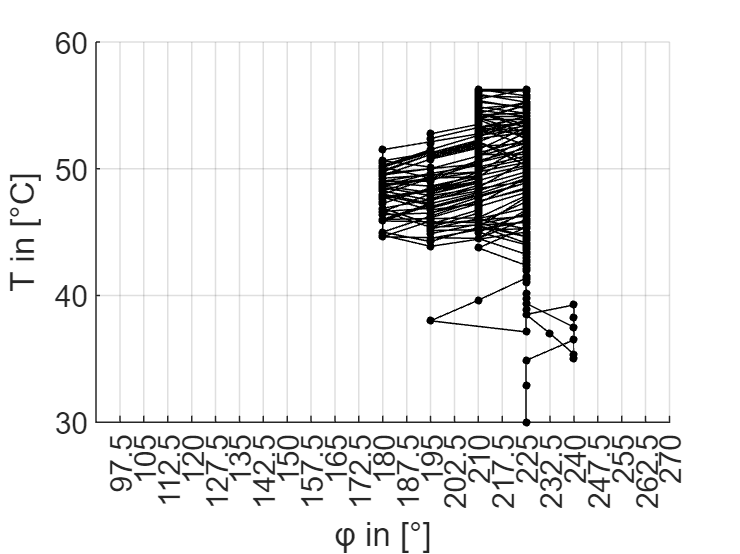

for i = 1:numel(tableStruct_Cycles)
    t = tableStruct_Cycles(i).tableContents;
    %% visualize test plan
    testplan_visualization(t); 

    %% time cross-sectional animation
    timeCrossSection_animation(sensor_position,t,1);

    %% animation of T_max position 
    maxT_position_animation(sensor_position,t);
end

## Plateau Data

Visualization

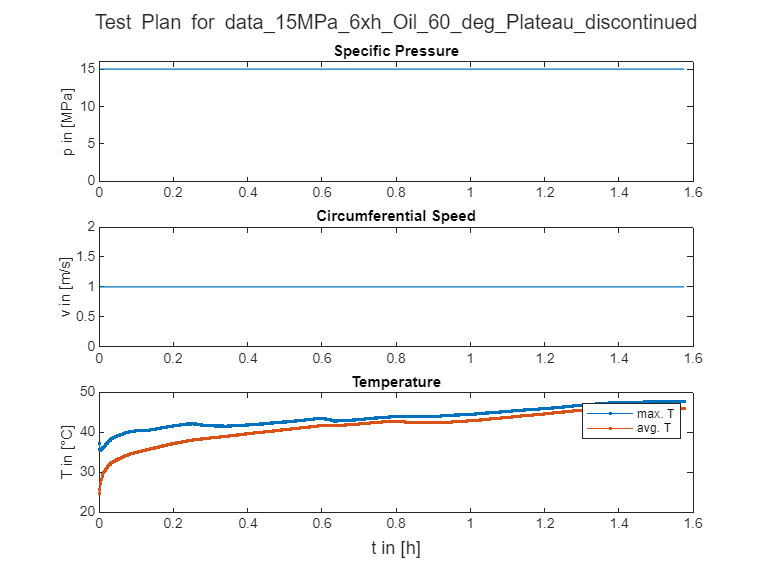

The documented max. T reached 47.75 ℃.


Animation for data_15MPa_6xh_Oil_60_deg_Plateau_discontinued: 


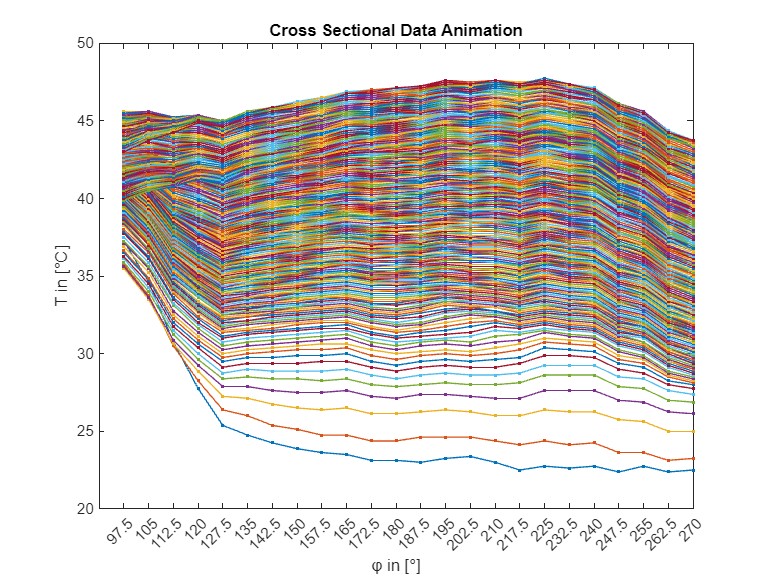

T_max position of data_15MPa_6xh_Oil_60_deg_Plateau_discontinued: 


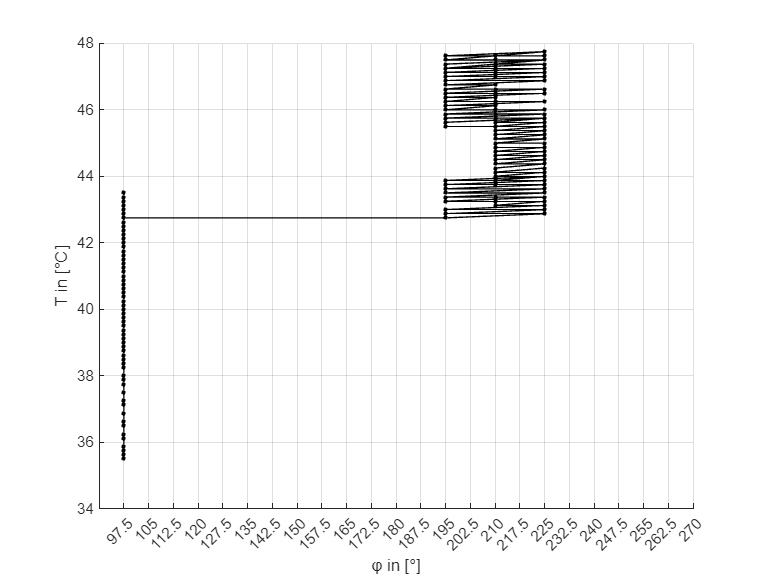

for i = 1:numel(tableStruct_Plateau)
    t = tableStruct_Plateau(i).tableContents;
    %% visualize test plan
    testplan_visualization(t); 

    %% time cross-sectional animation
    timeCrossSection_animation(sensor_position,t,1);

    %% animation of T_max position 
    maxT_position_animation(sensor_position,t);
end